# Figure 3: S_Ilgn and S_Elgn

clear

## 1. Select background parameters

CurrentFolder = pwd

CurrentFolder = 'C:\Users\tiexu\OneDrive\文档\Researches\NYU-Vision\MFModel Code'

FigurePath = [CurrentFolder '/Figures'];
addpath(CurrentFolder)
addpath([CurrentFolder '/Utils'])
addpath([CurrentFolder '/Data'])
addpath([CurrentFolder '/HPCData'])

S_EEtest = [0.018 0.021 0.024 0.027 0.030]; 
S_IItest = [0.08  0.12  0.16  0.20];

S_EEInd = 3; S_IIInd = 2;
S_EE = S_EEtest(S_EEInd);
S_II = S_IItest(S_IIInd);

rE_L6 = 0.25;
rI_L6test  = [1.5 3 4.5 6] * rE_L6;
rI_L6Ind = 3; % 2 or 3

S_Ilgnhold = [1.5 2 2.5 3];%*S_Elgn
S_Elgntest = [1.5 2 2.5 3.0]*S_EE;

Panel2 = length(S_Elgntest);
Panel1 = length(S_Ilgnhold);

## 4. Good Areas

white frE = [3 5], frI/frE = (3, 4.25)

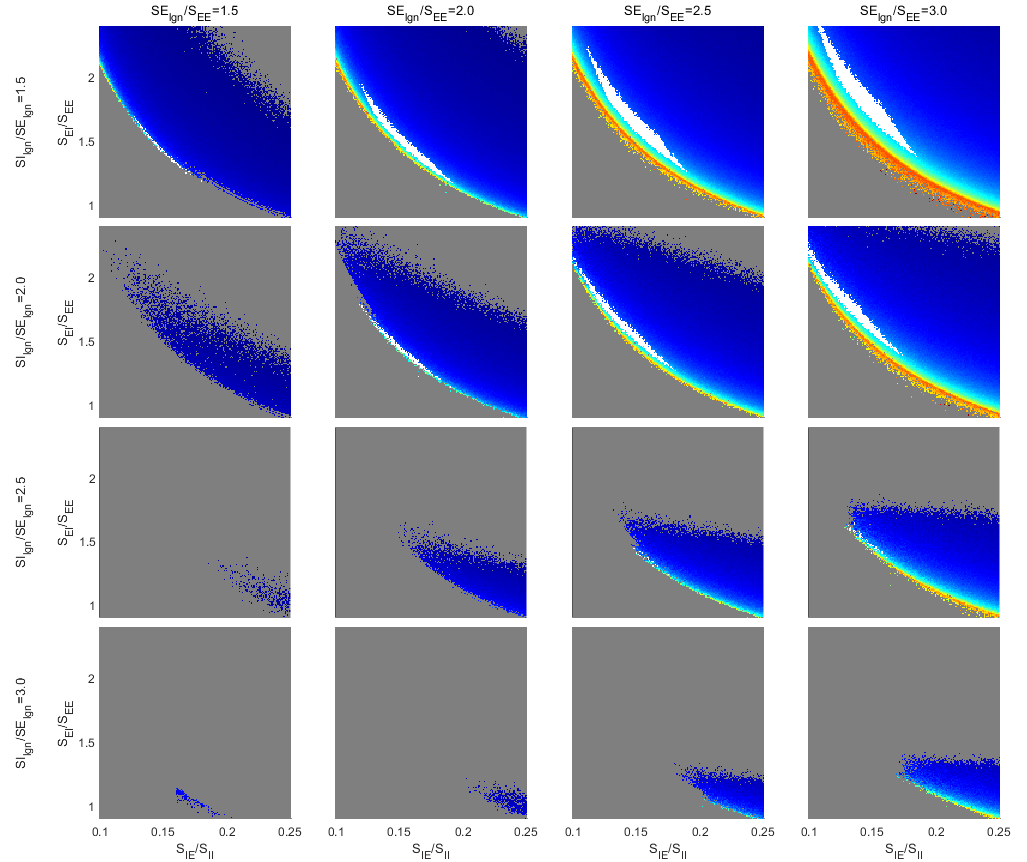

ans = 'id1 = 1.5, id2 = 1.5, Fail = 0.60, SIEWgt = 1.07'

ans = 'id1 = 1.5, id2 = 2.0, Fail = 0.71, SIEWgt = 1.16'

ans = 'id1 = 1.5, id2 = 2.5, Fail = 0.72, SIEWgt = 1.17'

ans = 'id1 = 1.5, id2 = 3.0, Fail = 0.73, SIEWgt = 1.17'

ans = 'id1 = 2.0, id2 = 1.5, Fail = 0.20, SIEWgt = 1.29'

ans = 'id1 = 2.0, id2 = 2.0, Fail = 0.43, SIEWgt = 1.15'

ans = 'id1 = 2.0, id2 = 2.5, Fail = 0.59, SIEWgt = 1.13'

ans = 'id1 = 2.0, id2 = 3.0, Fail = 0.71, SIEWgt = 1.15'

ans = 'id1 = 2.5, id2 = 1.5, Fail = 0.02, SIEWgt = 1.37'

ans = 'id1 = 2.5, id2 = 2.0, Fail = 0.11, SIEWgt = 1.51'

ans = 'id1 = 2.5, id2 = 2.5, Fail = 0.22, SIEWgt = 1.40'

ans = 'id1 = 2.5, id2 = 3.0, Fail = 0.30, SIEWgt = 1.36'

ans = 'id1 = 3.0, id2 = 1.5, Fail = 0.05, SIEWgt = 0.35'

ans = 'id1 = 3.0, id2 = 2.0, Fail = 0.03, SIEWgt = 0.91'

ans = 'id1 = 3.0, id2 = 2.5, Fail = 0.07, SIEWgt = 1.49'

ans = 'id1 = 3.0, id2 = 3.0, Fail = 0.11, SIEWgt = 1.54'

Fig1 = figure('Name','S_Ilgn_S_Elgn','units','normalized','outerposition',[0 0 0.67 1]);

ha = tight_subplot(Panel1,Panel2,[.01 .01],[.05 .03],[.08 .01]);

for S_IlgnInd = 1:length(S_Ilgntest)
       
    for S_ElgnInd = 1:length(S_Elgntest)
        
        S_Elgn=S_Elgntest(S_ElgnInd);
        
        S_Ilgntest = [1.5 2 2.5 3]*S_Elgn;
        S_Ilgn = S_Ilgntest(S_IlgnInd);
                    
        CurrentPanelFile = sprintf('FigContourL_S_EE=%.3f_S_II=%.2f_S_ElgnInd=%d_S_IlgnInd%d_rI_L6Ind%d.mat',...
                                               S_EE,     S_II,     S_ElgnInd,   S_IlgnInd,  rI_L6Ind);
        if isfile([CurrentFolder '/HPCData/' CurrentPanelFile])
        load(sprintf('FigContourL_S_EE=%.3f_S_II=%.2f_S_ElgnInd=%d_S_IlgnInd%d_rI_L6Ind%d.mat',...
                                 S_EE,     S_II,     S_ElgnInd,   S_IlgnInd,  rI_L6Ind),'ContourData_7D')
        else 
            continue
        end 
        
        % First axis for fr
        axes(ha(S_ElgnInd+Panel2*(S_IlgnInd-1)));
        ax1a = gca;
        %subplot(ContourData_7D.PanelNum2, ContourData_7D.PanelNum1,
        %rI_L6Ind+ContourData_7D.PanelNum2*(S_IlgnInd-1))
        hold on
        CurrentFrE = squeeze(ContourData_7D.Fr_NoFix(1,:,: )); %CurrentFrE(CurrentFrE<eps) = nan;
        CurrentFrE(CurrentFrE<=0) = 0;
        CurrentFrI = squeeze(ContourData_7D.Fr_NoFix(2,:,: ));
        CurrentBlowup = squeeze(logical(ContourData_7D.FailIndi(:,:)));
        CurrentSteady = squeeze(~ContourData_7D.ConvIndi(:,:));
        
        FailMap = CurrentBlowup | CurrentSteady;
        
        CurrentFrE(CurrentFrE>=3 & CurrentFrE<=5 & ...
            CurrentFrI./CurrentFrE    >=3 & ...
            CurrentFrI./CurrentFrE    <=4.25) = nan;
        CurrentFrE(FailMap) = nan;
        imagesc(ContourData_7D.S_IEtest/S_II,ContourData_7D.S_EItest/S_EE, CurrentFrE)
        set(gca,'YDir','normal')
        cmap = [1,1,1; jet];
        
        colormap(ax1a,cmap);  caxis([-0.1 15]); %colorbar;
        
        
        % set ticks, labels, titles, etc.
        if S_IlgnInd == 1
            title(sprintf('SE_{lgn}/S_{EE}=%.1f',S_Elgn/S_EE)) 
        end
        if S_ElgnInd == 1
            ylabel({sprintf('SI_{lgn}/SE_{lgn}=%.1f',S_Ilgn/S_Elgn),'','S_{EI}/S_{EE}'})
        else
            set(gca,'yticklabel','')
        end
        
        
        if S_IlgnInd == length(S_Ilgntest)
            xlabel('S_{IE}/S_{II}');
        else
            set(gca,'xticklabel','')
        end
        
        axis square
        axis tight
        
        % second axis for blowup+unsteady
        originalSize = get(ax1a, 'Position');
        ax1b = axes('Position',originalSize); 
        
        NoFailWeight = sum(double(~FailMap),'all')/(size(FailMap,1)*size(FailMap,2));
        SIEInds = repmat((1:size(FailMap,2)),size(FailMap,1),1);
        SIEWeight = mean(SIEInds(~FailMap))/mean(SIEInds(:));
        
        
        GreyHem = 0.5*ones(size(CurrentFrE));
        if NoFailWeight<0.11 || SIEWeight<1 % if impossible pattern show up on the left...
            FailMap(:,1:floor(size(FailMap,1)*0.4)) = true;
            
            
            
        end
        
        GreyHemAlpha = double(FailMap);
        im1b = imagesc(ContourData_7D.S_IEtest/S_II,ContourData_7D.S_EItest/S_EE,GreyHem);
        im1b.AlphaData = GreyHemAlpha; % change this value to change the foreground image transparency
        axis square;
        %link axes
        linkaxes([ax1a,ax1b])
        %%Hide the top axes
        ax1b.Visible = 'off';
        ax1b.XTick = [];
        ax1b.YTick = [];
        set(ax1b,'YDir','normal')
        %add differenct colormap to different data if you wish      
        colormap(ax1b,[0.5,0.5,0.5])
        
        
        sprintf('id1 = %.1f, id2 = %.1f, Fail = %.2f, SIEWgt = %.2f',...
                S_Ilgn/S_Elgn,S_Elgn/S_EE,NoFailWeight,SIEWeight)
        
    end
end

Save figures

% MF_7Dpath = [FigurePath '\MF_7D_fine\'];
% FigName1 = sprintf('GoodArea_SElgnInd%d_SIlgnInd%d_rIL6Ind%d_rE',...
%                              S_ElgnInd, S_IlgnInd, rI_L6Ind) ;
% FigName2 = sprintf('GoodArea_SElgnInd%d_SIlgnInd%d_rIL6Ind%d_rRatio',...
%                              S_ElgnInd, S_IlgnInd, rI_L6Ind) ;
% savefig(Fig1,[MF_7Dpath FigName1 '.fig']);
% savefig(Fig2,[MF_7Dpath FigName2 '.fig']);

Print Figs

% Fig1.PaperUnits = 'centimeters';
% Fig1.PaperSize = [41.95,25.68];
% Fig1.PaperOrientation = "landscape";
% exportgraphics(Fig1,[MF_7Dpath FigName1 '.pdf'],'Resolution',600)
% exportgraphics(Fig2,[MF_7Dpath FigName2 '.pdf'],'Resolution',600)

